%load images and labels
crop_size = 64;

[test, train, test_labels, train_labels, test_names, train_names] = load_images(crop_size);

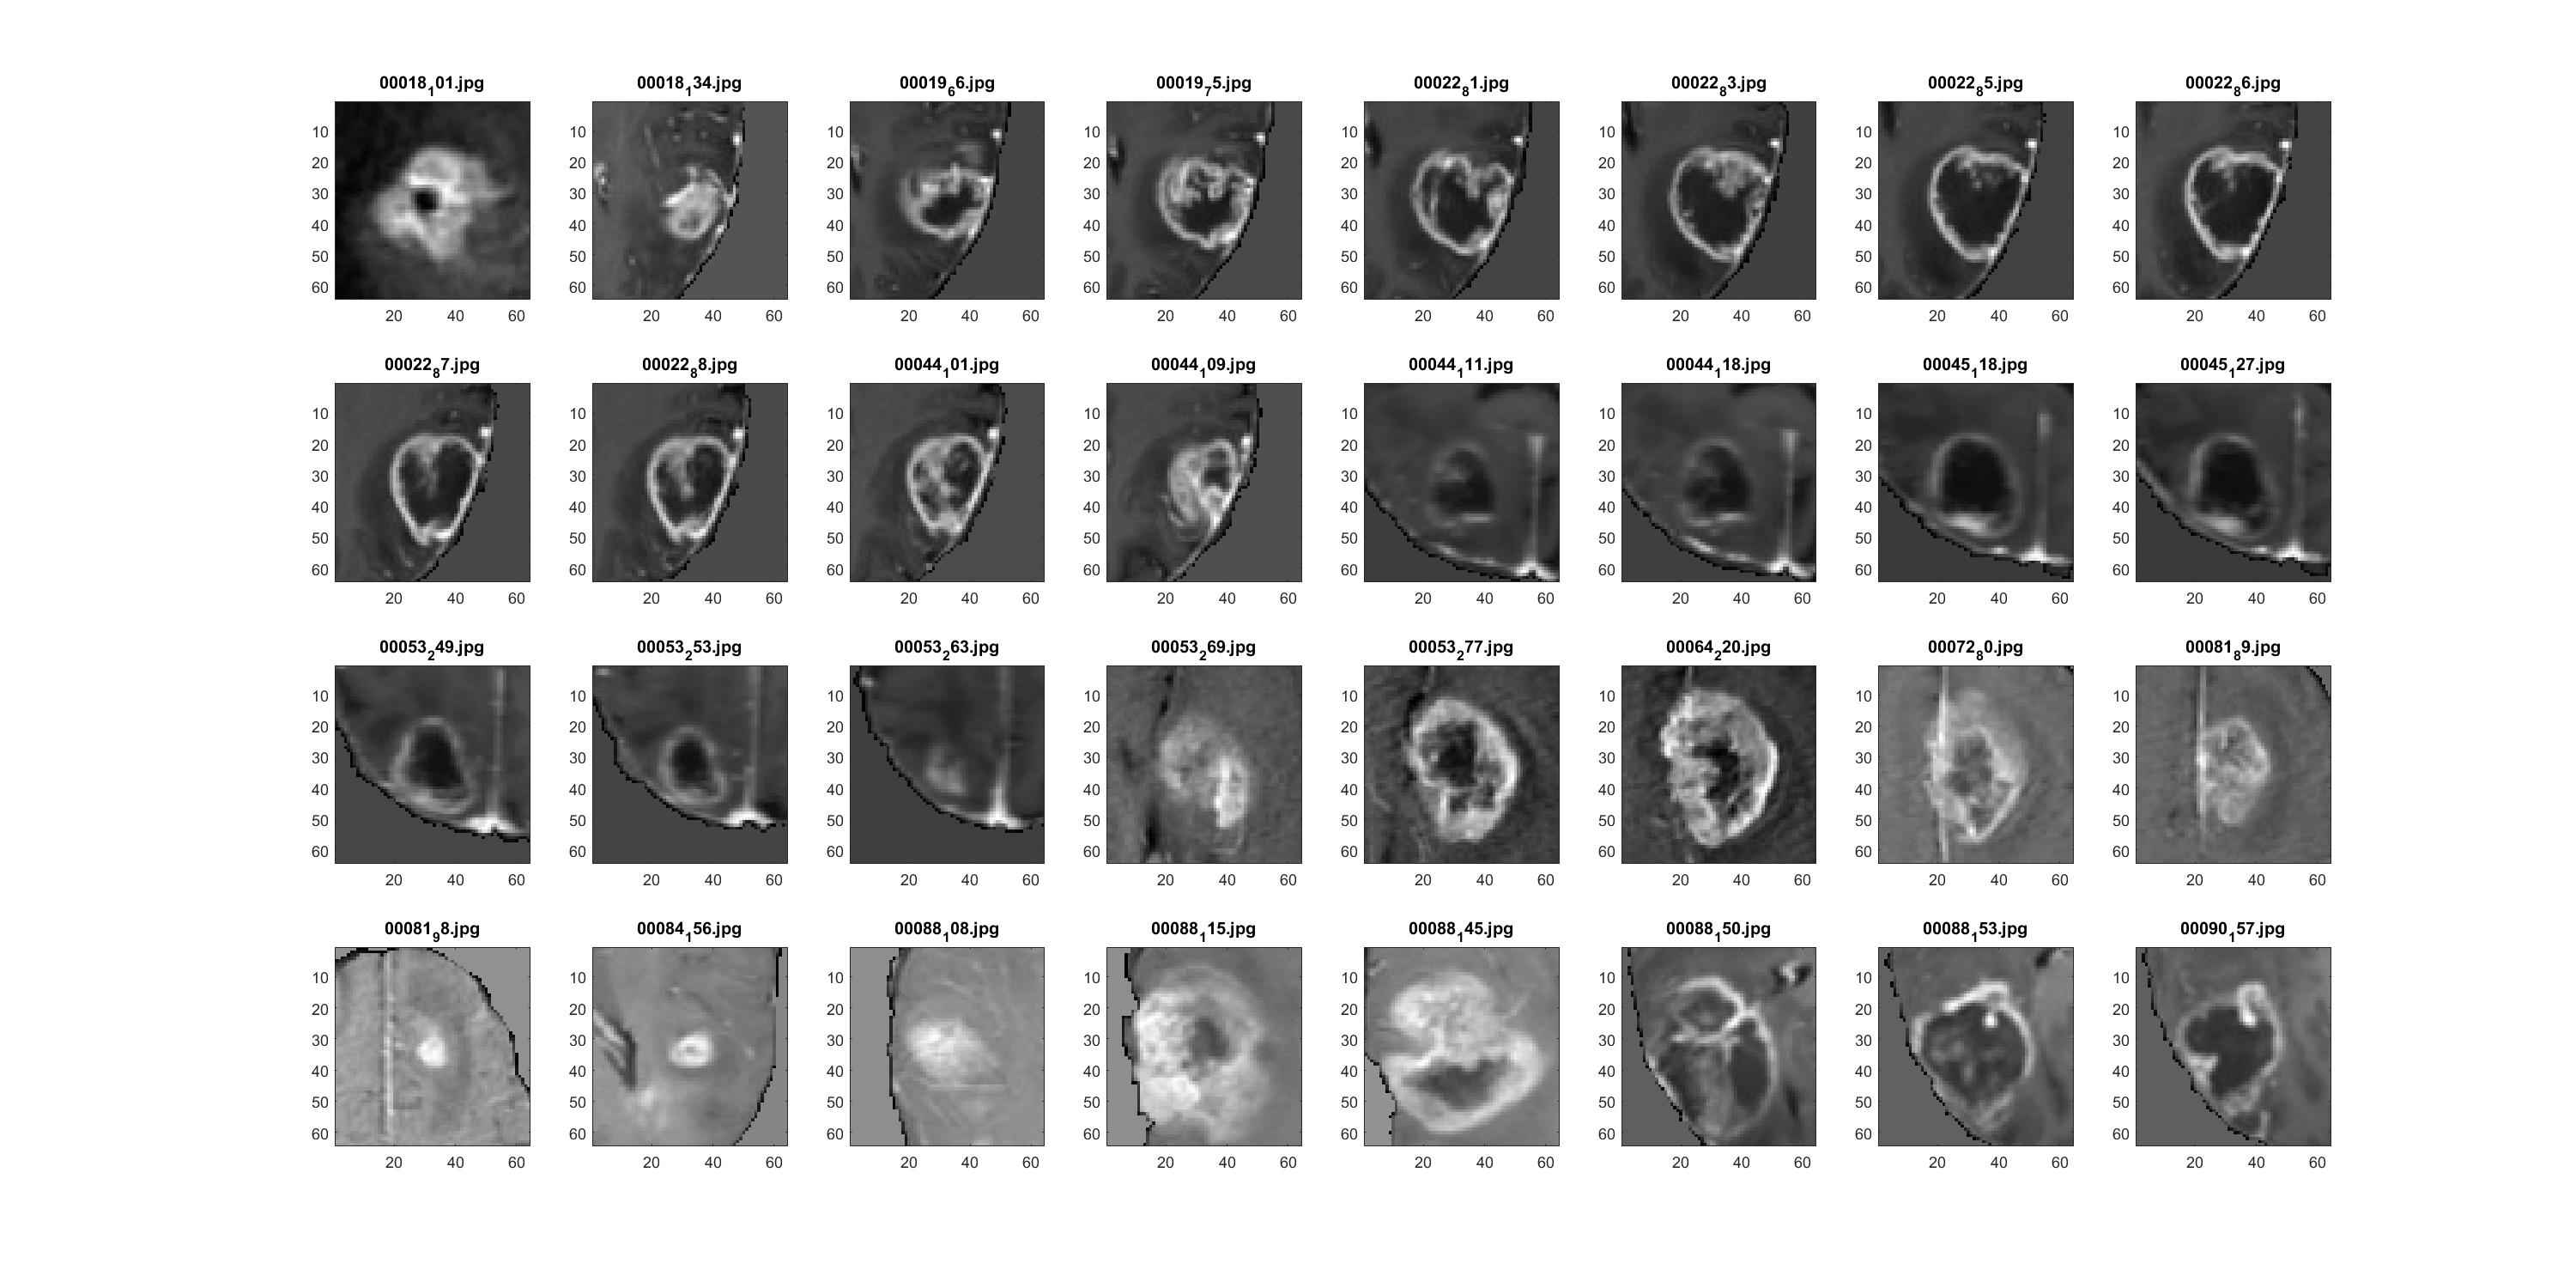

%plot
figure(1)
clf
set(figure(1), "Position", [0 0 2000 1000])
 for i=1:32
     subplot(4,8,i)
     imagesc(reshape(train(i,:), 64, 64))
     title(test_names{i})
     
 end
 colormap 'gray'

%PCA
 train_mc = train - mean(train, 2);
 R = train_mc' * train_mc;
 [V, D] = eigs(R, 50);

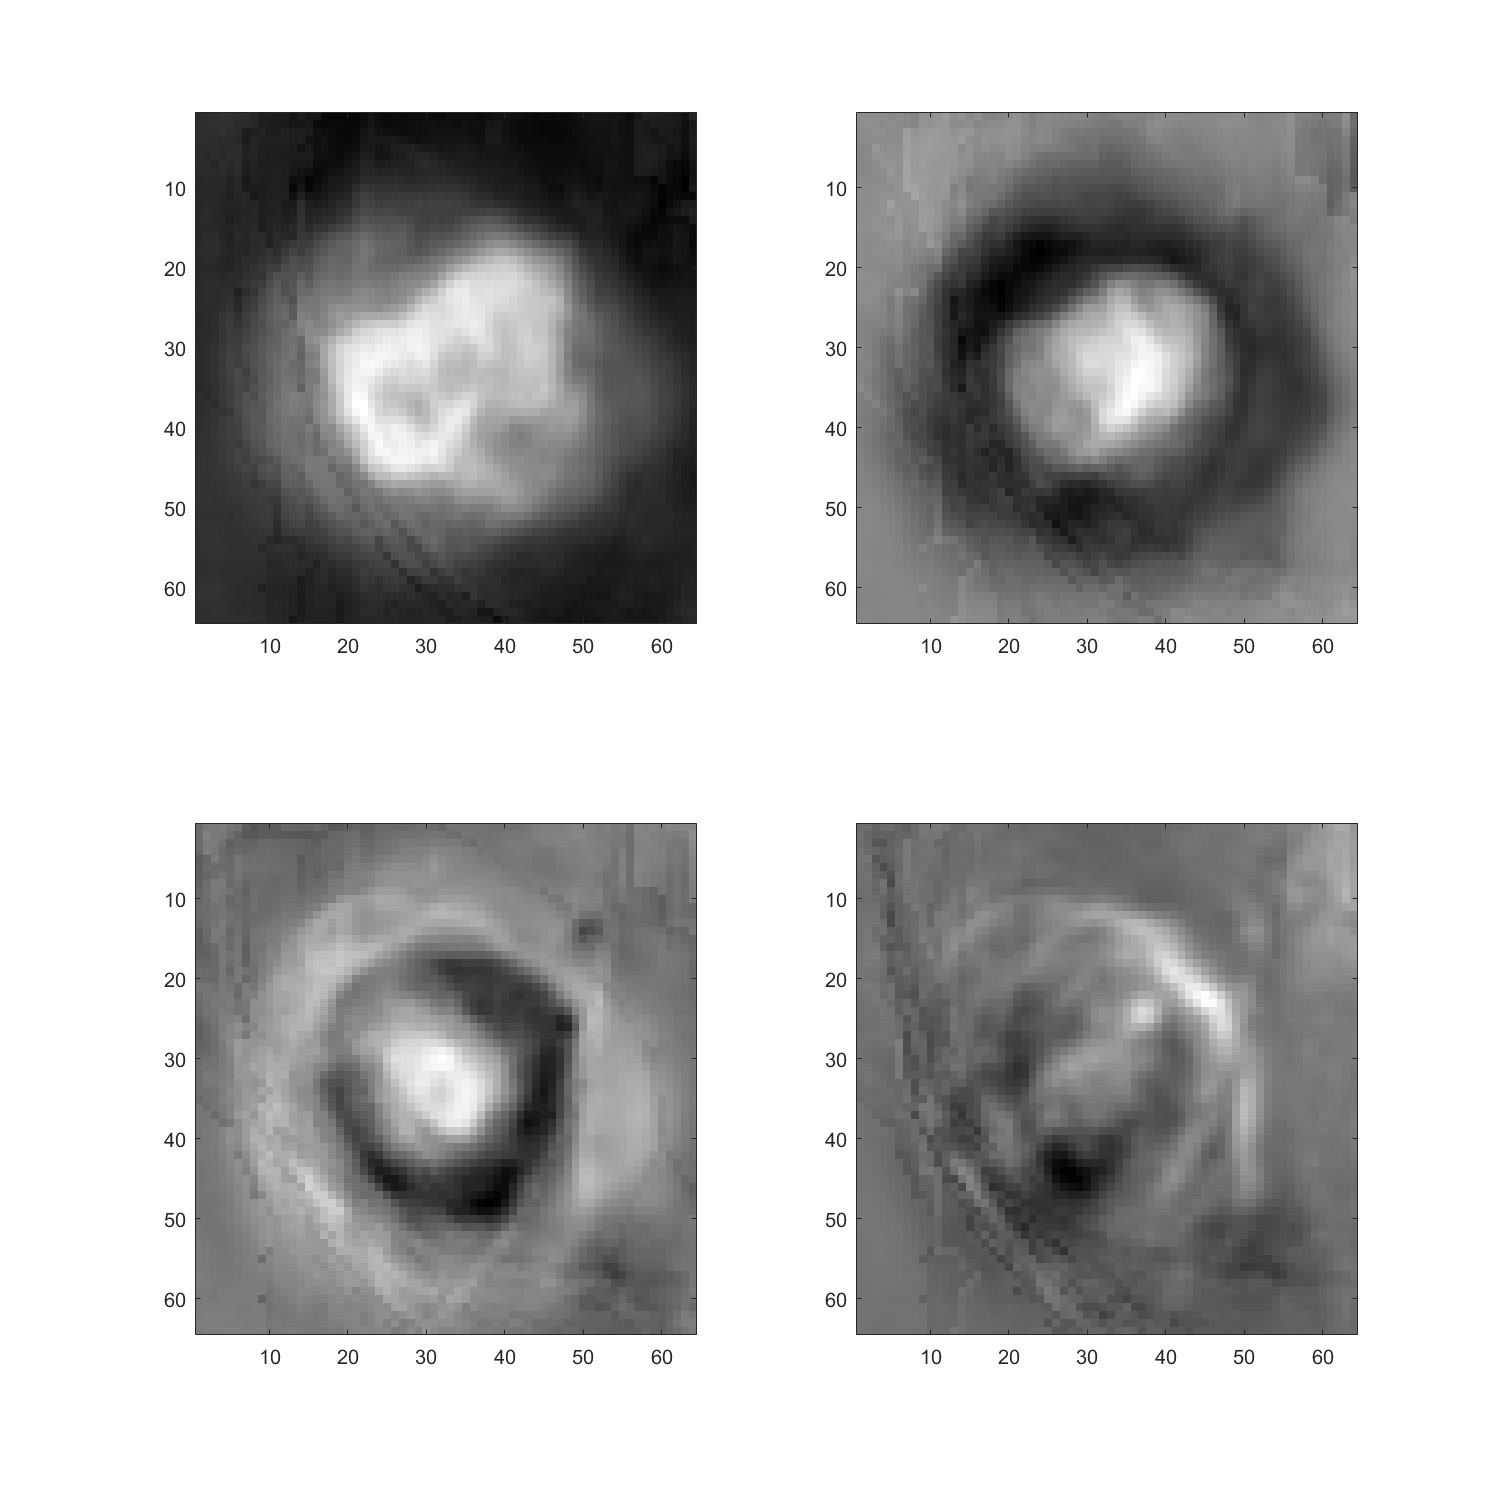

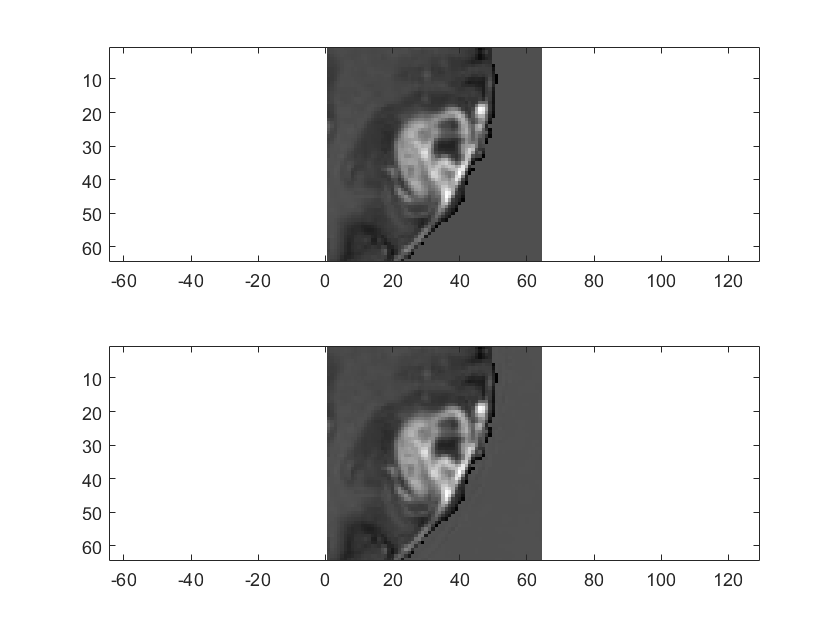

ans = 37.1946

%plot tumor space
 figure(2)
 clf
set(figure(2), "Position", [0 0 1000 1000])
 for i=1:4
     subplot(2,2,i)
     imagesc(reshape(V(:,i), crop_size, crop_size))
     %axis equal
 end
 colormap 'gray'

heat_map = zeros(256-crop_size, 256-crop_size);

% k = 13;
% wholeimage = test(k,:);
% wholeimage = reshape(wholeimage, 256, 256);

wholeimage = double(imread("axial_t1wce_2_class\images\train\00097_72.jpg"));
img = reshape(wholeimage, 1, []);
i1 = img < 10;
i2 = img >= 10;
img(i1) = mean(img(i2));

wholeimage = reshape(img, 256, 256);



 
for i=1:256 - crop_size + 1
        for j=1:256 - crop_size + 1

         
        subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
        subimage = reshape(subimage, 1, []);
        
        subimage = subimage - mean(subimage);
        
        si_comp = subimage * V;
        si_restr  = si_comp * V';
        
        epsilon = norm(si_restr - subimage);
        heat_map(i, j) = epsilon;
        end
end
heat_map = add_border(heat_map, crop_size);

figure(9)
clf
set(figure(9), 'Position')

  0×0 empty cell array


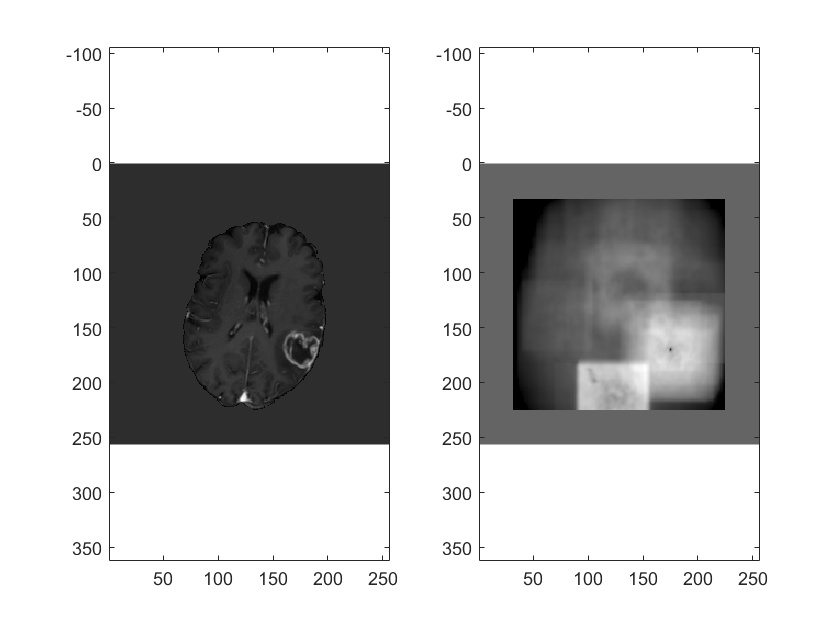

Max_col = 175

Max_row = 170

ans =   175.1736  141.3709


subplot(1,2,1)
imagesc(wholeimage)
axis equal
subplot(1,2,2)
imagesc(heat_map)
axis equal
colormap 'gray'

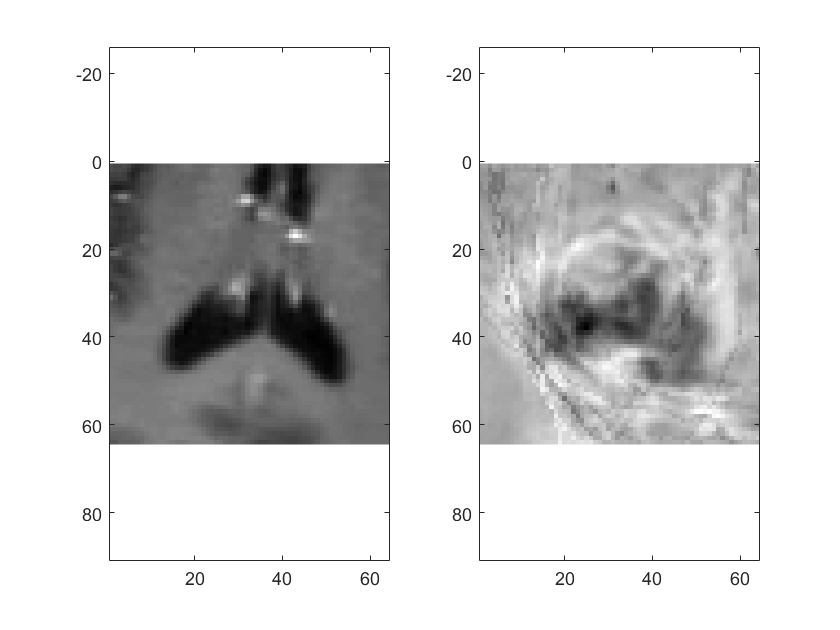

k = 13;
img = test(k,:);
i1 = img < 10;
    i2 = img >= 10;
    img(i1) = mean(img(i2));
    img = img- mean(img);
    
    
img = crop_img(reshape(img, 256, 256), [0.5 0.6], crop_size);
img = reshape(img, 1, []);


img_comp = img * V;
img_res = img_comp * V';




figure(5)
clf
subplot(1,2,1)
imagesc(reshape(img, crop_size, crop_size))
axis equal
subplot(1,2,2)
imagesc(reshape(img_res, crop_size, crop_size))
colormap 'gray'
axis equal


norm(img-img_res)

ans = 750.2736